# Homework 2: One-layer perceptron


$$\underline{x}^{(\mu)}=[x_1^{(\mu)}, x_2^{(\mu)}]^T$$



$$t^{\mu}=\pm1$$


Start by normalizing the data by centering each of the two input components and normalizing their respective variances to 1.

Your task is to train a perceptron with one fully-connected hidden layer, two input terminals and one output unit. Use the following network layout:

clc
clear
syms x
training_set = readmatrix("training_set.csv");
validation_set = readmatrix("validation_set.csv");
g = tanh(x);
eta = 0.0005;
N = 2;
epoch_n = 1000;
error_criteria = 0.12;

## Preprocessing

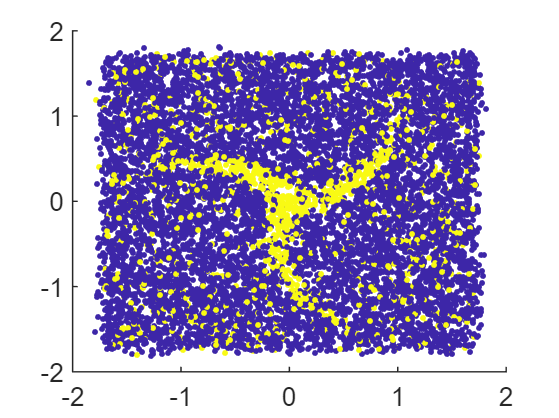

train_input_raw = training_set(:,1:2);
train_input = normalize(train_input_raw)';      % [2x10000]
target = training_set(:,3);                     % [10000x1]
figure
scatter(train_input(1,:),train_input(2,:),[],target,'.')

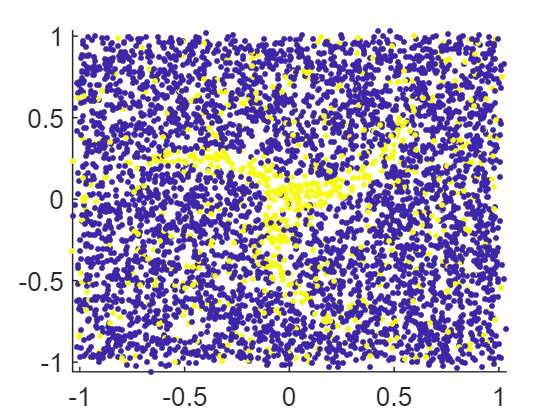

p = size(train_input,2);

figure
validation_input = validation_set(:,1:2)';      % [2x5000]
validation_target = validation_set(:,3);        % [5000x1]
scatter(validation_input(1,:),validation_input(2,:),[],validation_target,'.')

p_val = size(validation_input,2);

## Initialization

Different number of hidden neurons in the hidden layer.

M = 8;  % M goes to 100???
w = normrnd(0, 1, [M,2]);     % [Mx2] w_jk
theta = zeros([M,1]);           % [Mx1] theta_j
W = normrnd(0, 1, [1, M]);    % [1xM] W_ij i=1
Theta = 0;
V = zeros([M,1]);               % [Mx1] V_j
Out = 0;
H_train = [];
H_val = [];

## Set energy function

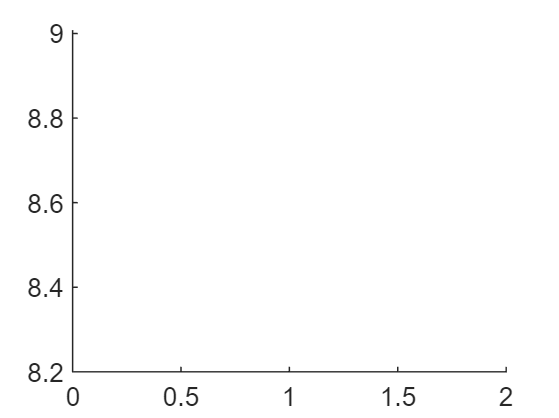

figure
hold on
H_train(end+1) = energy(W, w, Theta, theta, train_input, target);
H_val(end+1) = energy(W, w, Theta, theta, validation_input, validation_target);
plot(1:length(H_train),log(H_train))
plot(1:length(H_val),log(H_val))

## Training

for ep=1:epoch_n
    for nu = 1 : p
        mu = randi([1,p]);
        x_mu = train_input(:,mu); % randomly pick an input from training set
        t_mu = target(mu);
    
        % propagate forward
        b_mu = w*x_mu-theta;    % [3x1]
        V = tanh(b_mu);         % activation function g = tanh()
        B_mu = W*V-Theta;  % scalar
        Out = tanh(B_mu);       % scalar
        % end of propagate forward
    
        % back propagation
        %% Calculate Delta
%         Delta = (target(mu) - Out) * eval(subs(diff(g), B_mu));
        Delta = (target(mu) - Out) * (1-tanh(B_mu)^2);
       
        %% Calculate delta
%         delta = Delta * W'.* eval(subs(diff(g), b_mu));
        delta = Delta * W'.* (1-tanh(b_mu).^2);

        %% update W and w
        delta_w = eta * delta * x_mu';
        delta_W = eta * Delta * V';

        W = W + delta_W;
        w = w + delta_w;
        
        %% update Theta
        delta_Theta = -eta * Delta;
        Theta = Theta + delta_Theta;
    
        %% update theta
        delta_theta = -eta*delta;
        theta = theta + delta_theta; 
        % end of back propagation
    end
    W
    w
    H_train(end+1) = energy(W, w, Theta, theta, train_input, target);
    H_val(end+1) = energy(W, w, Theta, theta, validation_input, validation_target);
    
    plot(1:length(H_train),log(H_train))
    plot(1:length(H_val),log(H_val))
    legend('H\_train','H\_val')

    b = w*validation_input-theta;
    V = tanh(b);
    B = W*V-Theta;
    C = 1/(2*p_val)*sum(abs(validation_target'-sign(B)));

    if C < error_criteria
        disp('Classification error criteria is met');
        disp(['Epoch: ',num2str(ep),' C: ',num2str(C)])
        break
    else
        disp(['Epoch: ',num2str(ep),' C: ',num2str(C)])
    end
end

W =    -1.6901    0.1930   -0.7678   -0.2756    0.3819   -0.3239   -0.4131    1.0207


w =    -0.3142   -0.9424
   -0.2297   -0.1008
    0.0679    2.4214
   -0.4417   -1.0794
    0.3542   -1.5504
   -0.2431    0.0155
   -0.8205    0.4704
   -1.8239   -0.2254


Epoch: 1 C: 0.1516


W =    -1.6731    0.1787   -0.7567   -0.2761    0.3733   -0.3413   -0.4483    0.9335


w =    -0.3472   -0.8915
   -0.2159   -0.1013
    0.0775    2.4189
   -0.4439   -1.0757
    0.3546   -1.5463
   -0.2624    0.0167
   -0.8394    0.4494
   -1.8096   -0.2402


Epoch: 2 C: 0.1516


W =    -1.6496    0.1770   -0.7458   -0.2672    0.3584   -0.3424   -0.4480    0.8966


w =    -0.3174   -0.8663
   -0.2128   -0.1005
    0.0948    2.4153
   -0.4385   -1.0755
    0.3498   -1.5440
   -0.2626    0.0170
   -0.8467    0.4345
   -1.8009   -0.2470


Epoch: 3 C: 0.1516


W =    -1.6230    0.1749   -0.7412   -0.2537    0.3492   -0.3474   -0.4584    0.8498


w =    -0.2898   -0.8242
   -0.2075   -0.1011
    0.1132    2.4109
   -0.4329   -1.0741
    0.3455   -1.5415
   -0.2656    0.0199
   -0.8584    0.4183
   -1.7899   -0.2662


Epoch: 4 C: 0.1516


W =    -1.5997    0.1769   -0.7352   -0.2388    0.3372   -0.3541   -0.4679    0.8023


w =    -0.2510   -0.7799
   -0.2024   -0.1022
    0.1364    2.4037
   -0.4263   -1.0736
    0.3399   -1.5379
   -0.2668    0.0240
   -0.8707    0.3996
   -1.7742   -0.2828


Epoch: 5 C: 0.1516


W =    -1.5907    0.1799   -0.7069   -0.2386    0.3091   -0.3574   -0.4657    0.7691


w =    -0.2121   -0.7687
   -0.1993   -0.1013
    0.1607    2.3915
   -0.4201   -1.0763
    0.3360   -1.5316
   -0.2643    0.0237
   -0.8793    0.3789
   -1.7641   -0.2803


Epoch: 6 C: 0.1516


W =    -1.5690    0.1871   -0.7010   -0.2219    0.3004   -0.3620   -0.4685    0.7467


w =    -0.1794   -0.7429
   -0.1963   -0.1050
    0.1849    2.3777
   -0.4137   -1.0780
    0.3319   -1.5259
   -0.2601    0.0317
   -0.8854    0.3641
   -1.7543   -0.2876


Epoch: 7 C: 0.1516


W =    -1.5506    0.1933   -0.6923   -0.2081    0.2923   -0.3658   -0.4741    0.7335


w =    -0.1532   -0.7323
   -0.1932   -0.1099
    0.2067    2.3615
   -0.4083   -1.0808
    0.3298   -1.5192
   -0.2558    0.0400
   -0.8913    0.3542
   -1.7469   -0.2938


Epoch: 8 C: 0.1516


W =    -1.5384    0.1997   -0.6777   -0.2041    0.2791   -0.3726   -0.4844    0.7162


w =    -0.1360   -0.7372
   -0.1891   -0.1141
    0.2275    2.3426
   -0.4041   -1.0853
    0.3297   -1.5106
   -0.2528    0.0476
   -0.8993    0.3430
   -1.7388   -0.2973


Epoch: 9 C: 0.1516


W =    -1.5262    0.2056   -0.6720   -0.1974    0.2712   -0.3794   -0.4985    0.7007


w =    -0.1205   -0.7430
   -0.1843   -0.1183
    0.2522    2.3232
   -0.4011   -1.0883
    0.3301   -1.5029
   -0.2500    0.0557
   -0.9112    0.3324
   -1.7306   -0.3033


Epoch: 10 C: 0.1516


W =    -1.5136    0.2154   -0.6688   -0.1918    0.2682   -0.3910   -0.5117    0.6864


w =    -0.1154   -0.7547
   -0.1794   -0.1240
    0.2705    2.3032
   -0.3995   -1.0923
    0.3317   -1.4955
   -0.2474    0.0649
   -0.9196    0.3249
   -1.7256   -0.3073


Epoch: 11 C: 0.1516


W =    -1.5058    0.2208   -0.6651   -0.1904    0.2629   -0.3958   -0.5260    0.6811


w =    -0.1066   -0.7750
   -0.1753   -0.1282
    0.2877    2.2851
   -0.3978   -1.0960
    0.3345   -1.4887
   -0.2428    0.0718
   -0.9317    0.3166
   -1.7189   -0.3105


Epoch: 12 C: 0.1516


W =    -1.4917    0.2288   -0.6774   -0.1810    0.2698   -0.4062   -0.5495    0.6759


w =    -0.1028   -0.7884
   -0.1694   -0.1344
    0.3036    2.2667
   -0.3963   -1.0988
    0.3374   -1.4829
   -0.2402    0.0830
   -0.9484    0.3120
   -1.7110   -0.3268


Epoch: 13 C: 0.1516


W =    -1.4862    0.2361   -0.6772   -0.1807    0.2667   -0.4117   -0.5584    0.6876


w =    -0.0950   -0.8136
   -0.1670   -0.1379
    0.3187    2.2484
   -0.3944   -1.1028
    0.3412   -1.4767
   -0.2338    0.0892
   -0.9564    0.3093
   -1.7117   -0.3307


Epoch: 14 C: 0.1516


W =    -1.4845    0.2439   -0.6749   -0.1856    0.2610   -0.4193   -0.5671    0.6866


w =    -0.0927   -0.8441
   -0.1635   -0.1399
    0.3304    2.2311
   -0.3942   -1.1068
    0.3456   -1.4704
   -0.2278    0.0928
   -0.9671    0.2997
   -1.7083   -0.3305


Epoch: 15 C: 0.1516


W =    -1.4779    0.2536   -0.6834   -0.1821    0.2580   -0.4298   -0.5776    0.6859


w =    -0.0829   -0.8683
   -0.1597   -0.1441
    0.3471    2.2166
   -0.3934   -1.1097
    0.3471   -1.4648
   -0.2229    0.0982
   -0.9773    0.2933
   -1.7064   -0.3294


Epoch: 16 C: 0.1516


W =    -1.4743    0.2573   -0.6908   -0.1826    0.2613   -0.4341   -0.5976    0.7031


w =    -0.0829   -0.8896
   -0.1556   -0.1477
    0.3546    2.2042
   -0.3933   -1.1122
    0.3519   -1.4598
   -0.2186    0.1026
   -0.9891    0.2943
   -1.7097   -0.3331


Epoch: 17 C: 0.1516


W =    -1.4620    0.2691   -0.7075   -0.1687    0.2666   -0.4448   -0.6100    0.7125


w =    -0.0642   -0.9048
   -0.1534   -0.1535
    0.3693    2.1955
   -0.3912   -1.1138
    0.3533   -1.4560
   -0.2118    0.1106
   -1.0006    0.2974
   -1.7125   -0.3376


Epoch: 18 C: 0.1516


W =    -1.4674    0.2710   -0.7001   -0.1803    0.2605   -0.4525   -0.6347    0.7123


w =    -0.0762   -0.9303
   -0.1462   -0.1538
    0.3732    2.1889
   -0.3931   -1.1160
    0.3597   -1.4512
   -0.2127    0.1094
   -1.0180    0.2903
   -1.7143   -0.3337


Epoch: 19 C: 0.1516


W =    -1.4568    0.2800   -0.7243   -0.1704    0.2710   -0.4592   -0.6417    0.7279


w =    -0.0666   -0.9401
   -0.1454   -0.1582
    0.3802    2.1866
   -0.3931   -1.1171
    0.3611   -1.4494
   -0.2050    0.1162
   -1.0262    0.2937
   -1.7176   -0.3379


Epoch: 20 C: 0.1516


W =    -1.4621    0.2779   -0.7230   -0.1808    0.2680   -0.4593   -0.6609    0.7342


w =    -0.0734   -0.9638
   -0.1409   -0.1590
    0.3827    2.1786
   -0.3948   -1.1194
    0.3665   -1.4445
   -0.2046    0.1154
   -1.0366    0.2891
   -1.7188   -0.3315


Epoch: 21 C: 0.1516


W =    -1.4702    0.2797   -0.7166   -0.1919    0.2596   -0.4625   -0.6710    0.7391


w =    -0.0744   -0.9796
   -0.1380   -0.1563
    0.3879    2.1773
   -0.3963   -1.1207
    0.3705   -1.4415
   -0.2007    0.1092
   -1.0463    0.2846
   -1.7222   -0.3241


Epoch: 22 C: 0.1516


W =    -1.4603    0.2878   -0.7332   -0.1818    0.2659   -0.4704   -0.6798    0.7485


w =    -0.0654   -0.9845
   -0.1359   -0.1600
    0.3974    2.1774
   -0.3965   -1.1209
    0.3714   -1.4403
   -0.1961    0.1149
   -1.0562    0.2855
   -1.7278   -0.3263


Epoch: 23 C: 0.1516


W =    -1.4598    0.2902   -0.7400   -0.1846    0.2695   -0.4758   -0.6968    0.7503


w =    -0.0730   -0.9966
   -0.1313   -0.1610
    0.4010    2.1754
   -0.3979   -1.1219
    0.3762   -1.4379
   -0.1960    0.1161
   -1.0694    0.2836
   -1.7281   -0.3289


Epoch: 24 C: 0.1516


W =    -1.4563    0.2928   -0.7481   -0.1803    0.2727   -0.4785   -0.7087    0.7592


w =    -0.0627   -1.0035
   -0.1294   -0.1629
    0.4091    2.1747
   -0.3978   -1.1223
    0.3793   -1.4359
   -0.1930    0.1173
   -1.0781    0.2860
   -1.7307   -0.3320


Epoch: 25 C: 0.1516


W = 1×8
   -1.4621    0.2921   -0.7477   -0.1887    0.2677   -0.4782   -0.7197    0.7697


w = 8×2
   -0.0634   -1.0176
   -0.1272   -0.1613
    0.4104    2.1726
   -0.3991   -1.1235
    0.3825   -1.4331
   -0.1903    0.1146
   -1.0885    0.2798
   -1.7337   -0.3278


Epoch: 26 C: 0.1516


W = 1×8
   -1.4673    0.2938   -0.7493   -0.1949    0.2659   -0.4780   -0.7262    0.7819


w = 8×2
   -0.0601   -1.0267
   -0.1278   -0.1585
    0.4171    2.1723
   -0.3998   -1.1246
    0.3867   -1.4325
   -0.1833    0.1105
   -1.1011    0.2801
   -1.7352   -0.3229


Epoch: 27 C: 0.1516


W = 1×8
   -1.4719    0.2962   -0.7488   -0.2039    0.2656   -0.4842   -0.7439    0.7738


w = 8×2
   -0.0726   -1.0434
   -0.1230   -0.1577
    0.4141    2.1725
   -0.4020   -1.1261
    0.3924   -1.4295
   -0.1847    0.1086
   -1.1157    0.2817
   -1.7361   -0.3204


Epoch: 28 C: 0.1516


W = 1×8
   -1.4690    0.2995   -0.7599   -0.2016    0.2719   -0.4876   -0.7499    0.7735


w = 8×2
   -0.0710   -1.0480
   -0.1223   -0.1581
    0.4118    2.1755
   -0.4026   -1.1263
    0.3954   -1.4289
   -0.1824    0.1095
   -1.1240    0.2874
   -1.7380   -0.3262


Epoch: 29 C: 0.1516


W = 1×8
   -1.4650    0.3024   -0.7685   -0.1977    0.2769   -0.4893   -0.7547    0.7822


w = 8×2
   -0.0680   -1.0508
   -0.1226   -0.1594
    0.4144    2.1782
   -0.4030   -1.1264
    0.3982   -1.4284
   -0.1786    0.1115
   -1.1310    0.2951
   -1.7412   -0.3281


Epoch: 30 C: 0.1516


W = 1×8
   -1.4650    0.3040   -0.7719   -0.1981    0.2804   -0.4889   -0.7630    0.7955


w = 8×2
   -0.0642   -1.0588
   -0.1230   -0.1597
    0.4149    2.1794
   -0.4035   -1.1270
    0.4027   -1.4270
   -0.1731    0.1126
   -1.1399    0.3025
   -1.7445   -0.3272


Epoch: 31 C: 0.1516


W = 1×8
   -1.4582    0.3086   -0.7873   -0.1899    0.2861   -0.4922   -0.7674    0.8006


w = 8×2
   -0.0512   -1.0613
   -0.1230   -0.1620
    0.4224    2.1838
   -0.4035   -1.1266
    0.4041   -1.4255
   -0.1686    0.1151
   -1.1440    0.3107
   -1.7481   -0.3293


Epoch: 32 C: 0.1516


W = 1×8
   -1.4708    0.3041   -0.7901   -0.2005    0.2778   -0.4867   -0.7724    0.8091


w = 8×2
   -0.0360   -1.0831
   -0.1231   -0.1587
    0.4278    2.1786
   -0.4019   -1.1286
    0.4070   -1.4214
   -0.1659    0.1088
   -1.1474    0.3074
   -1.7487   -0.3290


Epoch: 33 C: 0.1516


W = 1×8
   -1.4651    0.3084   -0.7772   -0.1976    0.2831   -0.4949   -0.7879    0.7993


w = 8×2
   -0.0485   -1.0817
   -0.1186   -0.1602
    0.4229    2.1839
   -0.4047   -1.1276
    0.4138   -1.4206
   -0.1690    0.1107
   -1.1622    0.3136
   -1.7508   -0.3329


Epoch: 34 C: 0.1516


W = 1×8
   -1.4673    0.3067   -0.7900   -0.2026    0.2923   -0.4933   -0.7993    0.8052


w = 8×2
   -0.0506   -1.0855
   -0.1175   -0.1583
    0.4189    2.1864
   -0.4063   -1.1276
    0.4181   -1.4202
   -0.1670    0.1062
   -1.1689    0.3167
   -1.7540   -0.3236


Epoch: 35 C: 0.1516


W = 1×8
   -1.4676    0.3095   -0.7913   -0.2029    0.2912   -0.4983   -0.8038    0.7943


w = 8×2
   -0.0464   -1.0877
   -0.1154   -0.1576
    0.4226    2.1951
   -0.4073   -1.1272
    0.4206   -1.4198
   -0.1683    0.1044
   -1.1761    0.3181
   -1.7556   -0.3295


Epoch: 36 C: 0.1516


W = 1×8
   -1.4704    0.3101   -0.7972   -0.2040    0.2898   -0.4968   -0.8014    0.8111


w = 8×2
   -0.0335   -1.0930
   -0.1171   -0.1556
    0.4269    2.1977
   -0.4066   -1.1276
    0.4221   -1.4199
   -0.1623    0.1016
   -1.1802    0.3155
   -1.7616   -0.3312


Epoch: 37 C: 0.1516


W = 1×8
   -1.4706    0.3098   -0.7995   -0.2058    0.2935   -0.4984   -0.8155    0.8130


w = 8×2
   -0.0367   -1.0968
   -0.1142   -0.1554
    0.4310    2.2001
   -0.4080   -1.1275
    0.4273   -1.4190
   -0.1638    0.1004
   -1.1901    0.3188
   -1.7641   -0.3328


Epoch: 38 C: 0.1516


W = 1×8
   -1.4831    0.3129   -0.7923   -0.2151    0.2805   -0.4997   -0.8063    0.8183


w = 8×2
   -0.0235   -1.1170
   -0.1172   -0.1516
    0.4362    2.2008
   -0.4065   -1.1302
    0.4302   -1.4170
   -0.1566    0.0937
   -1.1913    0.3207
   -1.7704   -0.3271


Epoch: 39 C: 0.1516


W = 1×8
   -1.4808    0.3079   -0.7952   -0.2196    0.2959   -0.4987   -0.8322    0.8120


w = 8×2
   -0.0462   -1.1169
   -0.1109   -0.1527
    0.4257    2.2051
   -0.4108   -1.1292
    0.4373   -1.4162
   -0.1642    0.0945
   -1.2010    0.3259
   -1.7708   -0.3280


Epoch: 40 C: 0.1516


W = 1×8
   -1.4827    0.3109   -0.8084   -0.2171    0.2904   -0.4960   -0.8192    0.8378


w = 8×2
   -0.0231   -1.1237
   -0.1170   -0.1510
    0.4422    2.2096
   -0.4085   -1.1304
    0.4368   -1.4165
   -0.1522    0.0933
   -1.2025    0.3289
   -1.7771   -0.3359


Epoch: 41 C: 0.1516


W = 1×8
   -1.4755    0.3144   -0.8144   -0.2152    0.3052   -0.5032   -0.8340    0.8239


w = 8×2
   -0.0423   -1.1219
   -0.1124   -0.1529
    0.4303    2.2192
   -0.4122   -1.1293
    0.4428   -1.4173
   -0.1565    0.0955
   -1.2127    0.3397
   -1.7811   -0.3360


Epoch: 42 C: 0.1516


W = 1×8
   -1.4898    0.3095   -0.8146   -0.2283    0.2974   -0.4975   -0.8395    0.8341


w = 8×2
   -0.0311   -1.1381
   -0.1128   -0.1480
    0.4346    2.2208
   -0.4118   -1.1309
    0.4469   -1.4150
   -0.1533    0.0874
   -1.2191    0.3328
   -1.7824   -0.3326


Epoch: 43 C: 0.1446


W = 1×8
   -1.4854    0.3159   -0.8208   -0.2229    0.3004   -0.5024   -0.8329    0.8431


w = 8×2
   -0.0247   -1.1391
   -0.1147   -0.1486
    0.4362    2.2292
   -0.4122   -1.1308
    0.4483   -1.4162
   -0.1471    0.0886
   -1.2217    0.3389
   -1.7898   -0.3347


Epoch: 44 C: 0.1516


W = 1×8
   -1.4924    0.3131   -0.8221   -0.2315    0.2992   -0.4999   -0.8363    0.8476


w = 8×2
   -0.0270   -1.1489
   -0.1141   -0.1457
    0.4363    2.2322
   -0.4135   -1.1318
    0.4517   -1.4150
   -0.1462    0.0841
   -1.2252    0.3385
   -1.7941   -0.3332


Epoch: 45 C: 0.1514


W = 1×8
   -1.4968    0.3109   -0.8320   -0.2392    0.3040   -0.4990   -0.8401    0.8497


w = 8×2
   -0.0350   -1.1506
   -0.1128   -0.1423
    0.4387    2.2389
   -0.4153   -1.1318
    0.4558   -1.4161
   -0.1474    0.0796
   -1.2322    0.3370
   -1.7979   -0.3388


Epoch: 46 C: 0.1404


W = 1×8
   -1.5097    0.3118   -0.8197   -0.2513    0.2939   -0.4997   -0.8409    0.8435


w = 8×2
   -0.0364   -1.1720
   -0.1140   -0.1389
    0.4386    2.2383
   -0.4153   -1.1348
    0.4619   -1.4136
   -0.1442    0.0750
   -1.2419    0.3410
   -1.7964   -0.3380


Epoch: 47 C: 0.1506


W = 1×8
   -1.4940    0.3147   -0.8374   -0.2372    0.3135   -0.5025   -0.8505    0.8472


w = 8×2
   -0.0379   -1.1566
   -0.1128   -0.1421
    0.4374    2.2516
   -0.4168   -1.1316
    0.4656   -1.4168
   -0.1436    0.0801
   -1.2493    0.3543
   -1.8006   -0.3486


Epoch: 48 C: 0.1516


W = 1×8
   -1.4992    0.3131   -0.8323   -0.2439    0.3123   -0.5001   -0.8522    0.8515


w = 8×2
   -0.0425   -1.1671
   -0.1130   -0.1408
    0.4338    2.2507
   -0.4181   -1.1326
    0.4696   -1.4160
   -0.1415    0.0786
   -1.2537    0.3539
   -1.8046   -0.3486


Epoch: 49 C: 0.1516


W = 1×8
   -1.5027    0.3120   -0.8399   -0.2468    0.3131   -0.4994   -0.8615    0.8541


w = 8×2
   -0.0325   -1.1723
   -0.1119   -0.1390
    0.4391    2.2553
   -0.4186   -1.1324
    0.4724   -1.4153
   -0.1396    0.0747
   -1.2605    0.3515
   -1.8057   -0.3465


Epoch: 50 C: 0.1396


W = 1×8
   -1.5066    0.3130   -0.8346   -0.2511    0.3086   -0.5008   -0.8592    0.8502


w = 8×2
   -0.0373   -1.1795
   -0.1119   -0.1374
    0.4434    2.2579
   -0.4191   -1.1334
    0.4756   -1.4158
   -0.1392    0.0736
   -1.2687    0.3503
   -1.8069   -0.3526


Epoch: 51 C: 0.1516


W = 1×8
   -1.5033    0.3118   -0.8437   -0.2500    0.3168   -0.4991   -0.8678    0.8576


w = 8×2
   -0.0393   -1.1732
   -0.1117   -0.1366
    0.4462    2.2680
   -0.4212   -1.1321
    0.4794   -1.4175
   -0.1371    0.0721
   -1.2756    0.3572
   -1.8094   -0.3574


Epoch: 52 C: 0.1474


W = 1×8
   -1.5081    0.3095   -0.8460   -0.2569    0.3179   -0.4973   -0.8681    0.8610


w = 8×2
   -0.0381   -1.1685
   -0.1117   -0.1313
    0.4473    2.2750
   -0.4232   -1.1305
    0.4828   -1.4188
   -0.1351    0.0645
   -1.2794    0.3563
   -1.8134   -0.3572


Epoch: 53 C: 0.1402


W = 1×8
   -1.5141    0.3099   -0.8377   -0.2610    0.3067   -0.4965   -0.8578    0.8639


w = 8×2
   -0.0295   -1.1693
   -0.1141   -0.1272
    0.4600    2.2798
   -0.4232   -1.1306
    0.4847   -1.4199
   -0.1297    0.0588
   -1.2821    0.3540
   -1.8163   -0.3634


Epoch: 54 C: 0.1516


W = 1×8
   -1.5073    0.3070   -0.8592   -0.2563    0.3225   -0.4928   -0.8680    0.8711


w = 8×2
   -0.0295   -1.1643
   -0.1137   -0.1279
    0.4620    2.2863
   -0.4241   -1.1290
    0.4883   -1.4214
   -0.1296    0.0602
   -1.2867    0.3643
   -1.8175   -0.3757


Epoch: 55 C: 0.1394


W = 1×8
   -1.5130    0.3103   -0.8486   -0.2629    0.3164   -0.4969   -0.8584    0.8551


w = 8×2
   -0.0340   -1.1687
   -0.1145   -0.1242
    0.4612    2.2917
   -0.4260   -1.1294
    0.4912   -1.4229
   -0.1277    0.0561
   -1.2930    0.3630
   -1.8140   -0.3770


Epoch: 56 C: 0.1516


W = 1×8
   -1.5150    0.3031   -0.8603   -0.2660    0.3238   -0.4870   -0.8655    0.8725


w = 8×2
   -0.0304   -1.1740
   -0.1157   -0.1233
    0.4661    2.2928
   -0.4264   -1.1295
    0.4953   -1.4213
   -0.1249    0.0546
   -1.2925    0.3709
   -1.8166   -0.3857


Epoch: 57 C: 0.1404


W = 1×8
   -1.5248    0.3046   -0.8476   -0.2801    0.3217   -0.4923   -0.8684    0.8609


w = 8×2
   -0.0453   -1.1819
   -0.1128   -0.1184
    0.4582    2.2973
   -0.4306   -1.1300
    0.5013   -1.4212
   -0.1272    0.0481
   -1.3013    0.3665
   -1.8199   -0.3836


Epoch: 58 C: 0.1442


W = 1×8
   -1.5222    0.3044   -0.8573   -0.2786    0.3271   -0.4937   -0.8765    0.8516


w = 8×2
   -0.0405   -1.1834
   -0.1101   -0.1186
    0.4575    2.3036
   -0.4324   -1.1284
    0.5036   -1.4206
   -0.1298    0.0485
   -1.3064    0.3676
   -1.8206   -0.3862


Epoch: 59 C: 0.1422


W = 1×8
   -1.5108    0.3058   -0.8654   -0.2692    0.3395   -0.4925   -0.8786    0.8704


w = 8×2
   -0.0400   -1.1742
   -0.1114   -0.1207
    0.4603    2.3086
   -0.4353   -1.1260
    0.5059   -1.4232
   -0.1240    0.0524
   -1.3093    0.3734
   -1.8263   -0.3893


Epoch: 60 C: 0.1398


W = 1×8
   -1.5227    0.3078   -0.8553   -0.2794    0.3264   -0.4946   -0.8710    0.8747


w = 8×2
   -0.0320   -1.1828
   -0.1130   -0.1150
    0.4654    2.3118
   -0.4354   -1.1272
    0.5079   -1.4233
   -0.1190    0.0442
   -1.3158    0.3662
   -1.8315   -0.3901


Epoch: 61 C: 0.1516


W = 1×8
   -1.5227    0.3074   -0.8571   -0.2807    0.3308   -0.4930   -0.8735    0.8820


w = 8×2
   -0.0301   -1.1879
   -0.1135   -0.1152
    0.4578    2.3175
   -0.4377   -1.1271
    0.5094   -1.4234
   -0.1156    0.0443
   -1.3181    0.3672
   -1.8345   -0.3901


Epoch: 62 C: 0.145


W = 1×8
   -1.5270    0.3069   -0.8479   -0.2857    0.3294   -0.4910   -0.8731    0.8869


w = 8×2
   -0.0315   -1.1919
   -0.1152   -0.1130
    0.4562    2.3208
   -0.4398   -1.1275
    0.5136   -1.4245
   -0.1106    0.0418
   -1.3243    0.3650
   -1.8340   -0.3896


Epoch: 63 C: 0.1502


W = 1×8
   -1.5222    0.3038   -0.8667   -0.2835    0.3389   -0.4855   -0.8764    0.8946


w = 8×2
   -0.0291   -1.1883
   -0.1167   -0.1123
    0.4599    2.3269
   -0.4415   -1.1262
    0.5147   -1.4263
   -0.1069    0.0422
   -1.3292    0.3684
   -1.8310   -0.4019


Epoch: 64 C: 0.1402


W = 1×8
   -1.5339    0.3048   -0.8574   -0.2974    0.3336   -0.4883   -0.8763    0.8835


w = 8×2
   -0.0376   -1.1990
   -0.1160   -0.1077
    0.4560    2.3285
   -0.4438   -1.1279
    0.5191   -1.4263
   -0.1062    0.0358
   -1.3367    0.3655
   -1.8321   -0.3957


Epoch: 65 C: 0.1404


W = 1×8
   -1.5236    0.3051   -0.8639   -0.2897    0.3452   -0.4878   -0.8884    0.8825


w = 8×2
   -0.0398   -1.1921
   -0.1154   -0.1102
    0.4536    2.3354
   -0.4474   -1.1254
    0.5226   -1.4275
   -0.1057    0.0392
   -1.3459    0.3723
   -1.8334   -0.3990


Epoch: 66 C: 0.1412


W = 1×8
   -1.5314    0.3031   -0.8611   -0.2971    0.3388   -0.4847   -0.8855    0.8861


w = 8×2
   -0.0326   -1.1975
   -0.1172   -0.1063
    0.4590    2.3383
   -0.4481   -1.1258
    0.5246   -1.4277
   -0.1012    0.0340
   -1.3503    0.3670
   -1.8340   -0.4007


Epoch: 67 C: 0.1404


W = 1×8
   -1.5302    0.3041   -0.8587   -0.2926    0.3372   -0.4839   -0.8798    0.8976


w = 8×2
   -0.0187   -1.2003
   -0.1192   -0.1060
    0.4632    2.3405
   -0.4480   -1.1248
    0.5263   -1.4273
   -0.0966    0.0338
   -1.3507    0.3671
   -1.8392   -0.4078


Epoch: 68 C: 0.1434


W = 1×8
   -1.5321    0.3005   -0.8637   -0.3027    0.3464   -0.4845   -0.8936    0.8806


w = 8×2
   -0.0321   -1.1967
   -0.1137   -0.1028
    0.4533    2.3484
   -0.4543   -1.1221
    0.5298   -1.4271
   -0.1033    0.0287
   -1.3548    0.3627
   -1.8398   -0.4021


Epoch: 69 C: 0.14


W = 1×8
   -1.5305    0.3067   -0.8648   -0.2946    0.3408   -0.4879   -0.8847    0.8873


w = 8×2
   -0.0066   -1.1955
   -0.1188   -0.1019
    0.4585    2.3555
   -0.4526   -1.1214
    0.5300   -1.4288
   -0.0936    0.0277
   -1.3622    0.3710
   -1.8438   -0.4058


Epoch: 70 C: 0.1516


W = 1×8
   -1.5337    0.3041   -0.8792   -0.3015    0.3431   -0.4850   -0.8826    0.8953


w = 8×2
   -0.0052   -1.1992
   -0.1188   -0.0994
    0.4592    2.3607
   -0.4553   -1.1216
    0.5300   -1.4298
   -0.0923    0.0243
   -1.3599    0.3697
   -1.8496   -0.4098


Epoch: 71 C: 0.141


W = 1×8
   -1.5338    0.3056   -0.8714   -0.3032    0.3433   -0.4870   -0.8876    0.8910


w = 8×2
   -0.0126   -1.2019
   -0.1183   -0.0989
    0.4613    2.3639
   -0.4584   -1.1217
    0.5356   -1.4308
   -0.0918    0.0241
   -1.3721    0.3732
   -1.8474   -0.4194


Epoch: 72 C: 0.1508


W = 1×8
   -1.5396    0.3048   -0.8731   -0.3100    0.3423   -0.4848   -0.8881    0.8943


w = 8×2
   -0.0113   -1.2141
   -0.1200   -0.0970
    0.4590    2.3624
   -0.4600   -1.1236
    0.5370   -1.4310
   -0.0874    0.0220
   -1.3770    0.3717
   -1.8472   -0.4192


Epoch: 73 C: 0.1414


W = 1×8
   -1.5321    0.3033   -0.8916   -0.3055    0.3556   -0.4825   -0.9001    0.9040


w = 8×2
   -0.0113   -1.2167
   -0.1187   -0.0993
    0.4583    2.3659
   -0.4626   -1.1224
    0.5387   -1.4313
   -0.0873    0.0258
   -1.3814    0.3735
   -1.8505   -0.4275


Epoch: 74 C: 0.1432


W = 1×8
   -1.5323    0.3036   -0.8929   -0.3073    0.3609   -0.4839   -0.9112    0.8974


w = 8×2
   -0.0154   -1.2220
   -0.1168   -0.0991
    0.4594    2.3689
   -0.4648   -1.1222
    0.5438   -1.4311
   -0.0886    0.0256
   -1.3897    0.3796
   -1.8505   -0.4363


Epoch: 75 C: 0.141


W = 1×8
   -1.5408    0.3059   -0.8818   -0.3190    0.3538   -0.4889   -0.9107    0.8988


w = 8×2
   -0.0199   -1.2224
   -0.1152   -0.0941
    0.4632    2.3769
   -0.4697   -1.1220
    0.5480   -1.4323
   -0.0879    0.0185
   -1.3959    0.3726
   -1.8575   -0.4338


Epoch: 76 C: 0.1404


W = 1×8
   -1.5408    0.3087   -0.8839   -0.3156    0.3523   -0.4901   -0.9034    0.9010


w = 8×2
   -0.0046   -1.2228
   -0.1183   -0.0927
    0.4664    2.3836
   -0.4691   -1.1208
    0.5494   -1.4335
   -0.0820    0.0173
   -1.3997    0.3753
   -1.8603   -0.4375


Epoch: 77 C: 0.1458


W = 1×8
   -1.5440    0.3069   -0.8891   -0.3172    0.3481   -0.4845   -0.8853    0.9147


w = 8×2
    0.0065   -1.2263
   -0.1236   -0.0902
    0.4686    2.3875
   -0.4681   -1.1213
    0.5476   -1.4351
   -0.0737    0.0147
   -1.3947    0.3757
   -1.8648   -0.4398


Epoch: 78 C: 0.1424


W = 1×8
   -1.5393    0.3093   -0.8883   -0.3187    0.3585   -0.4892   -0.8943    0.9046


w = 8×2
   -0.0158   -1.2286
   -0.1199   -0.0918
    0.4620    2.3936
   -0.4737   -1.1208
    0.5523   -1.4366
   -0.0774    0.0176
   -1.3996    0.3797
   -1.8667   -0.4452


Epoch: 79 C: 0.1516


W = 1×8
   -1.5379    0.3050   -0.8980   -0.3202    0.3651   -0.4840   -0.9020    0.9159


w = 8×2
   -0.0173   -1.2283
   -0.1198   -0.0906
    0.4645    2.3984
   -0.4755   -1.1197
    0.5542   -1.4372
   -0.0769    0.0159
   -1.4049    0.3792
   -1.8727   -0.4481


Epoch: 80 C: 0.1398


W = 1×8
   -1.5397    0.3027   -0.8958   -0.3237    0.3714   -0.4810   -0.9119    0.9175


w = 8×2
   -0.0224   -1.2315
   -0.1202   -0.0892
    0.4622    2.4004
   -0.4778   -1.1194
    0.5608   -1.4379
   -0.0752    0.0137
   -1.4131    0.3877
   -1.8713   -0.4558


Epoch: 81 C: 0.1406


W = 1×8
   -1.5423    0.3059   -0.8916   -0.3268    0.3716   -0.4835   -0.9100    0.9218


w = 8×2
   -0.0231   -1.2362
   -0.1220   -0.0877
    0.4602    2.4033
   -0.4800   -1.1197
    0.5637   -1.4390
   -0.0699    0.0123
   -1.4192    0.3900
   -1.8761   -0.4564


Epoch: 82 C: 0.1392


W = 1×8
   -1.5423    0.3066   -0.8907   -0.3312    0.3790   -0.4860   -0.9218    0.9107


w = 8×2
   -0.0318   -1.2343
   -0.1200   -0.0858
    0.4530    2.4094
   -0.4850   -1.1180
    0.5699   -1.4405
   -0.0713    0.0098
   -1.4312    0.3935
   -1.8746   -0.4578


Epoch: 83 C: 0.14


W = 1×8
   -1.5456    0.3057   -0.8893   -0.3342    0.3765   -0.4846   -0.9187    0.9166


w = 8×2
   -0.0273   -1.2330
   -0.1214   -0.0824
    0.4606    2.4117
   -0.4855   -1.1170
    0.5724   -1.4417
   -0.0682    0.0051
   -1.4346    0.3932
   -1.8801   -0.4601


Epoch: 84 C: 0.141


W = 1×8
   -1.5457    0.3068   -0.9030   -0.3333    0.3756   -0.4837   -0.9140    0.9211


w = 8×2
   -0.0142   -1.2362
   -0.1248   -0.0804
    0.4672    2.4138
   -0.4853   -1.1171
    0.5714   -1.4441
   -0.0617    0.0035
   -1.4440    0.3900
   -1.8773   -0.4649


Epoch: 85 C: 0.1402


W = 1×8
   -1.5556    0.3057   -0.8970   -0.3416    0.3688   -0.4831   -0.9150    0.9243


w = 8×2
   -0.0069   -1.2464
   -0.1248   -0.0769
    0.4704    2.4153
   -0.4864   -1.1180
    0.5747   -1.4421
   -0.0603   -0.0022
   -1.4453    0.3903
   -1.8831   -0.4632


Epoch: 86 C: 0.1402


W = 1×8
   -1.5619    0.3060   -0.8988   -0.3509    0.3648   -0.4855   -0.9119    0.9229


w = 8×2
   -0.0028   -1.2496
   -0.1234   -0.0730
    0.4710    2.4214
   -0.4906   -1.1173
    0.5758   -1.4419
   -0.0610   -0.0075
   -1.4473    0.3817
   -1.8875   -0.4657


Epoch: 87 C: 0.1406


W = 1×8
   -1.5498    0.3025   -0.9171   -0.3446    0.3855   -0.4824   -0.9285    0.9280


w = 8×2
   -0.0065   -1.2374
   -0.1203   -0.0746
    0.4710    2.4296
   -0.4949   -1.1122
    0.5810   -1.4439
   -0.0644   -0.0054
   -1.4503    0.3907
   -1.8896   -0.4775


Epoch: 88 C: 0.1426


W = 1×8
   -1.5691    0.3052   -0.9075   -0.3640    0.3685   -0.4855   -0.9141    0.9216


w = 8×2
   -0.0034   -1.2546
   -0.1231   -0.0673
    0.4728    2.4294
   -0.4974   -1.1162
    0.5822   -1.4434
   -0.0580   -0.0152
   -1.4534    0.3837
   -1.8923   -0.4656


Epoch: 89 C: 0.1452


W = 1×8
   -1.5549    0.3110   -0.9157   -0.3513    0.3812   -0.4911   -0.9152    0.9302


w = 8×2
   -0.0036   -1.2455
   -0.1233   -0.0702
    0.4685    2.4374
   -0.5009   -1.1124
    0.5839   -1.4478
   -0.0552   -0.0100
   -1.4596    0.3894
   -1.8981   -0.4752


Epoch: 90 C: 0.1404


W = 1×8
   -1.5552    0.3064   -0.9182   -0.3562    0.3869   -0.4860   -0.9250    0.9378


w = 8×2
   -0.0070   -1.2426
   -0.1227   -0.0682
    0.4699    2.4399
   -0.5042   -1.1104
    0.5871   -1.4482
   -0.0549   -0.0128
   -1.4633    0.3871
   -1.9012   -0.4825


Epoch: 91 C: 0.1414


W = 1×8
   -1.5682    0.3028   -0.9094   -0.3742    0.3827   -0.4829   -0.9250    0.9334


w = 8×2
   -0.0164   -1.2520
   -0.1227   -0.0623
    0.4637    2.4414
   -0.5090   -1.1117
    0.5905   -1.4484
   -0.0535   -0.0211
   -1.4666    0.3795
   -1.9021   -0.4766


Epoch: 92 C: 0.1464


W = 1×8
   -1.5578    0.3078   -0.9157   -0.3621    0.3863   -0.4885   -0.9201    0.9365


w = 8×2
   -0.0029   -1.2401
   -0.1229   -0.0630
    0.4680    2.4501
   -0.5107   -1.1067
    0.5913   -1.4518
   -0.0516   -0.0195
   -1.4689    0.3846
   -1.9078   -0.4896


Epoch: 93 C: 0.1404


W = 1×8
   -1.5657    0.3042   -0.9048   -0.3717    0.3826   -0.4841   -0.9218    0.9349


w = 8×2
   -0.0078   -1.2457
   -0.1244   -0.0596
    0.4684    2.4520
   -0.5133   -1.1075
    0.5967   -1.4510
   -0.0495   -0.0252
   -1.4719    0.3913
   -1.9108   -0.4894


Epoch: 94 C: 0.1404


W = 1×8
   -1.5578    0.3024   -0.9148   -0.3707    0.3973   -0.4822   -0.9292    0.9376


w = 8×2
   -0.0188   -1.2425
   -0.1224   -0.0610
    0.4681    2.4540
   -0.5190   -1.1051
    0.6000   -1.4539
   -0.0507   -0.0224
   -1.4733    0.3896
   -1.9126   -0.4970


Epoch: 95 C: 0.1404


W = 1×8
   -1.5566    0.3055   -0.9162   -0.3667    0.3918   -0.4834   -0.9179    0.9373


w = 8×2
   -0.0068   -1.2480
   -0.1258   -0.0611
    0.4748    2.4552
   -0.5201   -1.1048
    0.5994   -1.4552
   -0.0443   -0.0211
   -1.4750    0.3899
   -1.9104   -0.5025


Epoch: 96 C: 0.1398


W = 1×8
   -1.5588    0.2989   -0.9213   -0.3771    0.4018   -0.4773   -0.9357    0.9374


w = 8×2
   -0.0208   -1.2491
   -0.1231   -0.0586
    0.4728    2.4584
   -0.5257   -1.1032
    0.6060   -1.4561
   -0.0471   -0.0246
   -1.4837    0.3882
   -1.9110   -0.5024


Epoch: 97 C: 0.1452


W = 1×8
   -1.5704    0.3004   -0.9142   -0.3857    0.3907   -0.4775   -0.9219    0.9433


w = 8×2
   -0.0122   -1.2620
   -0.1271   -0.0540
    0.4712    2.4599
   -0.5255   -1.1055
    0.6059   -1.4571
   -0.0397   -0.0305
   -1.4857    0.3813
   -1.9190   -0.4943


Epoch: 98 C: 0.146


W = 1×8
   -1.5681    0.3037   -0.9119   -0.3813    0.3866   -0.4797   -0.9179    0.9495


w = 8×2
   -0.0025   -1.2595
   -0.1300   -0.0529
    0.4779    2.4619
   -0.5266   -1.1040
    0.6067   -1.4593
   -0.0335   -0.0313
   -1.4943    0.3792
   -1.9206   -0.4999


Epoch: 99 C: 0.1412


W = 1×8
   -1.5636    0.3026   -0.9194   -0.3792    0.3948   -0.4782   -0.9240    0.9513


w = 8×2
   -0.0038   -1.2605
   -0.1297   -0.0534
    0.4790    2.4650
   -0.5296   -1.1021
    0.6098   -1.4598
   -0.0335   -0.0302
   -1.4987    0.3843
   -1.9257   -0.5059


Epoch: 100 C: 0.1422


W = 1×8
   -1.5611    0.3029   -0.9259   -0.3795    0.4026   -0.4791   -0.9272    0.9466


w = 8×2
   -0.0069   -1.2620
   -0.1285   -0.0535
    0.4775    2.4698
   -0.5329   -1.1004
    0.6142   -1.4605
   -0.0347   -0.0300
   -1.5009    0.3905
   -1.9281   -0.5106


Epoch: 101 C: 0.1412


W = 1×8
   -1.5681    0.3037   -0.9172   -0.3905    0.3987   -0.4805   -0.9269    0.9388


w = 8×2
   -0.0157   -1.2691
   -0.1289   -0.0493
    0.4789    2.4690
   -0.5384   -1.1006
    0.6180   -1.4610
   -0.0323   -0.0349
   -1.5088    0.3862
   -1.9265   -0.5124


Epoch: 102 C: 0.1402


W = 1×8
   -1.5544    0.3009   -0.9430   -0.3809    0.4110   -0.4758   -0.9308    0.9465


w = 8×2
   -0.0025   -1.2610
   -0.1290   -0.0516
    0.4861    2.4759
   -0.5421   -1.0954
    0.6170   -1.4625
   -0.0309   -0.0310
   -1.5085    0.3889
   -1.9257   -0.5239


Epoch: 103 C: 0.143


W = 1×8
   -1.5623    0.2987   -0.9266   -0.3863    0.4013   -0.4729   -0.9198    0.9524


w = 8×2
    0.0007   -1.2662
   -0.1310   -0.0481
    0.4889    2.4768
   -0.5428   -1.0950
    0.6201   -1.4618
   -0.0279   -0.0367
   -1.5051    0.3863
   -1.9354   -0.5234


Epoch: 104 C: 0.142


W = 1×8
   -1.5592    0.3008   -0.9196   -0.3879    0.4105   -0.4763   -0.9310    0.9407


w = 8×2
   -0.0149   -1.2669
   -0.1289   -0.0489
    0.4814    2.4827
   -0.5504   -1.0928
    0.6271   -1.4635
   -0.0292   -0.0354
   -1.5127    0.3904
   -1.9339   -0.5300


Epoch: 105 C: 0.1418


W = 1×8
   -1.5558    0.2982   -0.9315   -0.3863    0.4173   -0.4703   -0.9309    0.9553


w = 8×2
   -0.0096   -1.2679
   -0.1328   -0.0482
    0.4832    2.4846
   -0.5516   -1.0919
    0.6286   -1.4658
   -0.0221   -0.0359
   -1.5138    0.3938
   -1.9375   -0.5312


Epoch: 106 C: 0.141


W = 1×8
   -1.5707    0.2990   -0.9202   -0.4049    0.4086   -0.4747   -0.9304    0.9361


w = 8×2
   -0.0135   -1.2752
   -0.1306   -0.0411
    0.4808    2.4892
   -0.5562   -1.0919
    0.6322   -1.4657
   -0.0245   -0.0454
   -1.5222    0.3823
   -1.9409   -0.5274


Epoch: 107 C: 0.1402


W = 1×8
   -1.5691    0.2989   -0.9312   -0.4025    0.4127   -0.4717   -0.9207    0.9453


w = 8×2
   -0.0034   -1.2771
   -0.1352   -0.0400
    0.4797    2.4930
   -0.5553   -1.0914
    0.6313   -1.4685
   -0.0169   -0.0461
   -1.5231    0.3873
   -1.9432   -0.5321


Epoch: 108 C: 0.1428


W = 1×8
   -1.5667    0.2983   -0.9332   -0.4076    0.4216   -0.4719   -0.9316    0.9452


w = 8×2
   -0.0134   -1.2764
   -0.1333   -0.0391
    0.4718    2.4982
   -0.5636   -1.0889
    0.6356   -1.4702
   -0.0178   -0.0470
   -1.5290    0.3859
   -1.9436   -0.5322


Epoch: 109 C: 0.1442


W = 1×8
   -1.5636    0.3019   -0.9414   -0.4052    0.4244   -0.4751   -0.9257    0.9460


w = 8×2
   -0.0024   -1.2731
   -0.1355   -0.0377
    0.4680    2.5074
   -0.5679   -1.0857
    0.6361   -1.4744
   -0.0127   -0.0482
   -1.5344    0.3835
   -1.9447   -0.5308


Epoch: 110 C: 0.1412


W = 1×8
   -1.5728    0.2983   -0.9348   -0.4130    0.4232   -0.4709   -0.9287    0.9427


w = 8×2
   -0.0003   -1.2877
   -0.1359   -0.0352
    0.4686    2.5050
   -0.5685   -1.0869
    0.6417   -1.4719
   -0.0119   -0.0521
   -1.5370    0.3869
   -1.9451   -0.5364


Epoch: 111 C: 0.146


W = 1×8
   -1.5768    0.3011   -0.9366   -0.4166    0.4200   -0.4729   -0.9165    0.9467


w = 8×2
    0.0078   -1.2923
   -0.1389   -0.0324
    0.4694    2.5077
   -0.5702   -1.0873
    0.6410   -1.4744
   -0.0055   -0.0550
   -1.5368    0.3852
   -1.9473   -0.5385


Epoch: 112 C: 0.1464


W = 1×8
   -1.5726    0.3041   -0.9421   -0.4170    0.4262   -0.4763   -0.9178    0.9397


w = 8×2
    0.0003   -1.2944
   -0.1386   -0.0332
    0.4675    2.5127
   -0.5762   -1.0862
    0.6437   -1.4768
   -0.0047   -0.0531
   -1.5413    0.3892
   -1.9473   -0.5409


Epoch: 113 C: 0.142


W = 1×8
   -1.5707    0.3058   -0.9381   -0.4190    0.4342   -0.4786   -0.9257    0.9400


w = 8×2
   -0.0063   -1.2895
   -0.1386   -0.0316
    0.4593    2.5203
   -0.5820   -1.0832
    0.6501   -1.4801
   -0.0029   -0.0550
   -1.5499    0.3946
   -1.9492   -0.5459


Epoch: 114 C: 0.14


W = 1×8
   -1.5764    0.3050   -0.9373   -0.4260    0.4349   -0.4774   -0.9255    0.9413


w = 8×2
   -0.0073   -1.3026
   -0.1391   -0.0301
    0.4560    2.5212
   -0.5849   -1.0845
    0.6530   -1.4794
   -0.0013   -0.0568
   -1.5516    0.3934
   -1.9519   -0.5454


Epoch: 115 C: 0.1416


W = 1×8
   -1.5757    0.3082   -0.9429   -0.4243    0.4295   -0.4794   -0.9105    0.9494


w = 8×2
    0.0071   -1.3023
   -0.1431   -0.0280
    0.4589    2.5244
   -0.5867   -1.0832
    0.6493   -1.4826
    0.0061   -0.0588
   -1.5511    0.3909
   -1.9563   -0.5456


Epoch: 116 C: 0.143


W = 1×8
   -1.5698    0.3063   -0.9536   -0.4246    0.4406   -0.4761   -0.9152    0.9529


w = 8×2
    0.0062   -1.3000
   -0.1438   -0.0284
    0.4609    2.5271
   -0.5917   -1.0806
    0.6518   -1.4851
    0.0085   -0.0575
   -1.5534    0.3966
   -1.9586   -0.5492


Epoch: 117 C: 0.1438


W = 1×8
   -1.5680    0.3091   -0.9551   -0.4254    0.4434   -0.4801   -0.9185    0.9483


w = 8×2
    0.0084   -1.2968
   -0.1433   -0.0271
    0.4611    2.5335
   -0.5963   -1.0775
    0.6554   -1.4868
    0.0087   -0.0588
   -1.5619    0.3957
   -1.9609   -0.5552


Epoch: 118 C: 0.1402


W = 1×8
   -1.5774    0.3119   -0.9487   -0.4328    0.4344   -0.4837   -0.9143    0.9409


w = 8×2
    0.0220   -1.3035
   -0.1447   -0.0229
    0.4612    2.5364
   -0.5993   -1.0768
    0.6576   -1.4867
    0.0121   -0.0641
   -1.5675    0.3882
   -1.9631   -0.5526


Epoch: 119 C: 0.1402


W = 1×8
   -1.5705    0.3134   -0.9511   -0.4247    0.4383   -0.4837   -0.9188    0.9383


w = 8×2
    0.0282   -1.3052
   -0.1463   -0.0260
    0.4616    2.5410
   -0.6034   -1.0742
    0.6606   -1.4873
    0.0154   -0.0598
   -1.5749    0.3925
   -1.9625   -0.5592


Epoch: 120 C: 0.1414


W = 1×8
   -1.5837    0.3102   -0.9492   -0.4449    0.4325   -0.4810   -0.9192    0.9345


w = 8×2
    0.0218   -1.3157
   -0.1464   -0.0194
    0.4599    2.5400
   -0.6080   -1.0765
    0.6617   -1.4876
    0.0168   -0.0684
   -1.5785    0.3819
   -1.9628   -0.5573


Epoch: 121 C: 0.1432


W = 1×8
   -1.5785    0.3129   -0.9603   -0.4385    0.4391   -0.4824   -0.9148    0.9381


w = 8×2
    0.0309   -1.3152
   -0.1491   -0.0203
    0.4586    2.5469
   -0.6090   -1.0750
    0.6629   -1.4909
    0.0219   -0.0667
   -1.5813    0.3891
   -1.9643   -0.5651


Epoch: 122 C: 0.142


W = 1×8
   -1.5797    0.3151   -0.9609   -0.4431    0.4381   -0.4834   -0.9054    0.9436


w = 8×2
    0.0312   -1.3118
   -0.1534   -0.0172
    0.4581    2.5527
   -0.6121   -1.0757
    0.6630   -1.4957
    0.0296   -0.0705
   -1.5846    0.3891
   -1.9671   -0.5648


Epoch: 123 C: 0.1412


W = 1×8
   -1.5740    0.3169   -0.9640   -0.4425    0.4440   -0.4855   -0.9088    0.9467


w = 8×2
    0.0262   -1.3103
   -0.1530   -0.0175
    0.4567    2.5567
   -0.6180   -1.0732
    0.6643   -1.4987
    0.0307   -0.0690
   -1.5913    0.3862
   -1.9708   -0.5678


Epoch: 124 C: 0.14


W = 1×8
   -1.5772    0.3140   -0.9620   -0.4522    0.4451   -0.4827   -0.9164    0.9458


w = 8×2
    0.0205   -1.3159
   -0.1520   -0.0151
    0.4551    2.5568
   -0.6245   -1.0718
    0.6662   -1.4990
    0.0303   -0.0720
   -1.5957    0.3808
   -1.9746   -0.5672


Epoch: 125 C: 0.1414


W = 1×8
   -1.5679    0.3164   -0.9741   -0.4470    0.4572   -0.4844   -0.9209    0.9470


w = 8×2
    0.0182   -1.3124
   -0.1527   -0.0173
    0.4531    2.5623
   -0.6291   -1.0688
    0.6684   -1.5039
    0.0325   -0.0682
   -1.6022    0.3876
   -1.9770   -0.5742


Epoch: 126 C: 0.1402


W = 1×8
   -1.5730    0.3143   -0.9799   -0.4513    0.4555   -0.4811   -0.9178    0.9603


w = 8×2
    0.0299   -1.3159
   -0.1553   -0.0137
    0.4563    2.5660
   -0.6292   -1.0679
    0.6688   -1.5056
    0.0372   -0.0731
   -1.6031    0.3832
   -1.9825   -0.5747


Epoch: 127 C: 0.1466


W = 1×8
   -1.5707    0.3166   -0.9805   -0.4548    0.4603   -0.4848   -0.9191    0.9529


w = 8×2
    0.0287   -1.3100
   -0.1545   -0.0117
    0.4525    2.5771
   -0.6364   -1.0634
    0.6717   -1.5094
    0.0373   -0.0753
   -1.6071    0.3799
   -1.9844   -0.5772


Epoch: 128 C: 0.1414


W = 1×8
   -1.5769    0.3177   -0.9772   -0.4581    0.4540   -0.4847   -0.9158    0.9615


w = 8×2
    0.0373   -1.3163
   -0.1583   -0.0089
    0.4610    2.5786
   -0.6375   -1.0653
    0.6744   -1.5110
    0.0440   -0.0792
   -1.6125    0.3789
   -1.9854   -0.5809


Epoch: 129 C: 0.1426


W = 1×8
   -1.5794    0.3195   -0.9749   -0.4643    0.4547   -0.4872   -0.9125    0.9632


w = 8×2
    0.0364   -1.3200
   -0.1586   -0.0070
    0.4607    2.5805
   -0.6436   -1.0646
    0.6773   -1.5121
    0.0453   -0.0815
   -1.6132    0.3815
   -1.9923   -0.5810


Epoch: 130 C: 0.1418


W = 1×8
   -1.5732    0.3169   -0.9811   -0.4614    0.4661   -0.4828   -0.9197    0.9679


w = 8×2
    0.0333   -1.3215
   -0.1596   -0.0084
    0.4623    2.5831
   -0.6470   -1.0618
    0.6821   -1.5135
    0.0473   -0.0797
   -1.6180    0.3880
   -1.9952   -0.5864


Epoch: 131 C: 0.1426


W = 1×8
   -1.5813    0.3162   -0.9693   -0.4704    0.4607   -0.4822   -0.9161    0.9659


w = 8×2
    0.0277   -1.3295
   -0.1608   -0.0048
    0.4618    2.5823
   -0.6490   -1.0631
    0.6860   -1.5131
    0.0493   -0.0846
   -1.6211    0.3887
   -1.9982   -0.5939


Epoch: 132 C: 0.1416


W = 1×8
   -1.5840    0.3160   -0.9726   -0.4783    0.4578   -0.4823   -0.9154    0.9737


w = 8×2
    0.0301   -1.3345
   -0.1603   -0.0028
    0.4674    2.5846
   -0.6560   -1.0616
    0.6853   -1.5140
    0.0501   -0.0867
   -1.6233    0.3763
   -2.0049   -0.5920


Epoch: 133 C: 0.1442


W = 1×8
   -1.5847    0.3176   -0.9700   -0.4847    0.4622   -0.4843   -0.9203    0.9665


w = 8×2
    0.0238   -1.3345
   -0.1609   -0.0011
    0.4631    2.5913
   -0.6635   -1.0607
    0.6909   -1.5160
    0.0518   -0.0886
   -1.6303    0.3799
   -2.0070   -0.5894


Epoch: 134 C: 0.1418


W = 1×8
   -1.5784    0.3165   -0.9825   -0.4873    0.4711   -0.4830   -0.9270    0.9679


w = 8×2
    0.0203   -1.3315
   -0.1599   -0.0014
    0.4603    2.5973
   -0.6703   -1.0568
    0.6913   -1.5190
    0.0515   -0.0873
   -1.6348    0.3781
   -2.0105   -0.5961


Epoch: 135 C: 0.1444


W = 1×8
   -1.5830    0.3173   -0.9798   -0.4934    0.4685   -0.4843   -0.9288    0.9667


w = 8×2
    0.0226   -1.3380
   -0.1598    0.0005
    0.4661    2.5965
   -0.6741   -1.0564
    0.6936   -1.5196
    0.0520   -0.0895
   -1.6401    0.3769
   -2.0155   -0.5973


Epoch: 136 C: 0.1444


W = 1×8
   -1.5817    0.3207   -0.9833   -0.4945    0.4706   -0.4886   -0.9227    0.9690


w = 8×2
    0.0262   -1.3359
   -0.1606    0.0021
    0.4606    2.6061
   -0.6798   -1.0534
    0.6949   -1.5226
    0.0541   -0.0912
   -1.6399    0.3780
   -2.0219   -0.5998


Epoch: 137 C: 0.1414


W = 1×8
   -1.5842    0.3181   -0.9824   -0.5038    0.4773   -0.4866   -0.9309    0.9584


w = 8×2
    0.0230   -1.3354
   -0.1589    0.0052
    0.4577    2.6138
   -0.6860   -1.0498
    0.7017   -1.5233
    0.0519   -0.0955
   -1.6443    0.3791
   -2.0228   -0.6040


Epoch: 138 C: 0.1408


W = 1×8
   -1.5834    0.3213   -0.9849   -0.4972    0.4712   -0.4880   -0.9152    0.9733


w = 8×2
    0.0433   -1.3398
   -0.1639    0.0050
    0.4676    2.6146
   -0.6860   -1.0488
    0.6989   -1.5248
    0.0604   -0.0946
   -1.6411    0.3787
   -2.0297   -0.6048


Epoch: 139 C: 0.1418


W = 1×8
   -1.5794    0.3213   -0.9961   -0.4986    0.4804   -0.4869   -0.9179    0.9739


w = 8×2
    0.0410   -1.3411
   -0.1659    0.0057
    0.4627    2.6190
   -0.6900   -1.0466
    0.7010   -1.5276
    0.0645   -0.0947
   -1.6471    0.3822
   -2.0301   -0.6086


Epoch: 140 C: 0.144


W = 1×8
   -1.5867    0.3228   -0.9972   -0.5077    0.4751   -0.4893   -0.9147    0.9711


w = 8×2
    0.0526   -1.3476
   -0.1664    0.0094
    0.4700    2.6206
   -0.6954   -1.0456
    0.7012   -1.5286
    0.0662   -0.0988
   -1.6501    0.3706
   -2.0319   -0.6079


Epoch: 141 C: 0.1462


W = 1×8
   -1.5786    0.3240   -1.0011   -0.5065    0.4834   -0.4905   -0.9193    0.9706


w = 8×2
    0.0509   -1.3413
   -0.1661    0.0090
    0.4701    2.6262
   -0.7031   -1.0400
    0.7042   -1.5325
    0.0670   -0.0976
   -1.6555    0.3710
   -2.0342   -0.6149


Epoch: 142 C: 0.1422


W = 1×8
   -1.5880    0.3234   -0.9926   -0.5166    0.4748   -0.4900   -0.9153    0.9685


w = 8×2
    0.0532   -1.3523
   -0.1671    0.0125
    0.4739    2.6253
   -0.7060   -1.0411
    0.7070   -1.5299
    0.0689   -0.1023
   -1.6558    0.3682
   -2.0391   -0.6175


Epoch: 143 C: 0.1434


W = 1×8
   -1.5935    0.3182   -0.9916   -0.5302    0.4802   -0.4839   -0.9286    0.9610


w = 8×2
    0.0442   -1.3594
   -0.1674    0.0164
    0.4706    2.6231
   -0.7111   -1.0400
    0.7129   -1.5308
    0.0702   -0.1078
   -1.6648    0.3661
   -2.0384   -0.6148


Epoch: 144 C: 0.151


W = 1×8
   -1.5851    0.3214   -1.0066   -0.5210    0.4850   -0.4854   -0.9191    0.9747


w = 8×2
    0.0578   -1.3612
   -0.1710    0.0138
    0.4730    2.6232
   -0.7128   -1.0368
    0.7086   -1.5350
    0.0766   -0.1027
   -1.6646    0.3638
   -2.0449   -0.6209


Epoch: 145 C: 0.1518


W = 1×8
   -1.5866    0.3217   -0.9981   -0.5219    0.4832   -0.4853   -0.9135    0.9839


w = 8×2
    0.0519   -1.3664
   -0.1726    0.0153
    0.4694    2.6230
   -0.7148   -1.0354
    0.7113   -1.5370
    0.0794   -0.1048
   -1.6645    0.3634
   -2.0566   -0.6225


Epoch: 146 C: 0.1488


W = 1×8
   -1.5810    0.3230   -1.0008   -0.5191    0.4853   -0.4858   -0.9163    0.9851


w = 8×2
    0.0505   -1.3682
   -0.1739    0.0137
    0.4718    2.6254
   -0.7206   -1.0329
    0.7123   -1.5400
    0.0824   -0.1024
   -1.6712    0.3670
   -2.0572   -0.6292


Epoch: 147 C: 0.1462


W = 1×8
   -1.5817    0.3236   -1.0013   -0.5261    0.4929   -0.4875   -0.9234    0.9748


w = 8×2
    0.0436   -1.3730
   -0.1719    0.0146
    0.4651    2.6312
   -0.7286   -1.0303
    0.7182   -1.5416
    0.0801   -0.1030
   -1.6765    0.3649
   -2.0596   -0.6326


Epoch: 148 C: 0.144


W = 1×8
   -1.5685    0.3231   -1.0149   -0.5174    0.5068   -0.4848   -0.9258    0.9859


w = 8×2
    0.0436   -1.3711
   -0.1742    0.0109
    0.4719    2.6331
   -0.7320   -1.0266
    0.7207   -1.5451
    0.0842   -0.0973
   -1.6783    0.3732
   -2.0621   -0.6414


Epoch: 149 C: 0.1442


W = 1×8
   -1.5733    0.3255   -1.0084   -0.5304    0.5080   -0.4892   -0.9297    0.9764


w = 8×2
    0.0369   -1.3684
   -0.1728    0.0150
    0.4673    2.6428
   -0.7406   -1.0248
    0.7259   -1.5486
    0.0829   -0.1025
   -1.6842    0.3748
   -2.0662   -0.6385


Epoch: 150 C: 0.1412


W = 1×8
   -1.5828    0.3276   -0.9996   -0.5325    0.4986   -0.4904   -0.9218    0.9801


w = 8×2
    0.0493   -1.3791
   -0.1772    0.0177
    0.4686    2.6443
   -0.7413   -1.0262
    0.7292   -1.5479
    0.0897   -0.1064
   -1.6865    0.3768
   -2.0710   -0.6345


Epoch: 151 C: 0.142


W = 1×8
   -1.5828    0.3289   -1.0006   -0.5355    0.4992   -0.4909   -0.9206    0.9815


w = 8×2
    0.0528   -1.3859
   -0.1790    0.0175
    0.4654    2.6440
   -0.7473   -1.0255
    0.7295   -1.5497
    0.0934   -0.1055
   -1.6900    0.3741
   -2.0734   -0.6364


Epoch: 152 C: 0.1436


W = 1×8
   -1.5797    0.3282   -1.0108   -0.5411    0.5060   -0.4899   -0.9321    0.9789


w = 8×2
    0.0542   -1.3882
   -0.1791    0.0181
    0.4601    2.6487
   -0.7559   -1.0222
    0.7301   -1.5521
    0.0944   -0.1055
   -1.6965    0.3711
   -2.0775   -0.6351


Epoch: 153 C: 0.1478


W = 1×8
   -1.5732    0.3289   -1.0116   -0.5379    0.5136   -0.4903   -0.9355    0.9720


w = 8×2
    0.0506   -1.3875
   -0.1789    0.0160
    0.4604    2.6536
   -0.7620   -1.0179
    0.7336   -1.5554
    0.0948   -0.1025
   -1.7012    0.3741
   -2.0771   -0.6450


Epoch: 154 C: 0.1426


W = 1×8
   -1.5896    0.3323   -0.9958   -0.5444    0.4942   -0.4928   -0.9181    0.9832


w = 8×2
    0.0665   -1.3998
   -0.1861    0.0225
    0.4653    2.6497
   -0.7598   -1.0219
    0.7342   -1.5554
    0.1058   -0.1113
   -1.7024    0.3713
   -2.0834   -0.6382


Epoch: 155 C: 0.1446


W = 1×8
   -1.5917    0.3333   -0.9928   -0.5521    0.4968   -0.4941   -0.9175    0.9761


w = 8×2
    0.0558   -1.4057
   -0.1863    0.0238
    0.4547    2.6524
   -0.7669   -1.0217
    0.7367   -1.5577
    0.1067   -0.1127
   -1.7047    0.3684
   -2.0841   -0.6350


Epoch: 156 C: 0.1446


W = 1×8
   -1.5854    0.3362   -1.0061   -0.5479    0.5046   -0.4967   -0.9154    0.9759


w = 8×2
    0.0662   -1.4015
   -0.1889    0.0242
    0.4520    2.6600
   -0.7698   -1.0165
    0.7368   -1.5629
    0.1110   -0.1121
   -1.7097    0.3733
   -2.0873   -0.6399


Epoch: 157 C: 0.1438


W = 1×8
   -1.5772    0.3355   -1.0123   -0.5414    0.5113   -0.4945   -0.9166    0.9889


w = 8×2
    0.0759   -1.3928
   -0.1917    0.0246
    0.4526    2.6686
   -0.7728   -1.0087
    0.7376   -1.5671
    0.1156   -0.1125
   -1.7127    0.3746
   -2.0921   -0.6453


Epoch: 158 C: 0.1426


W = 1×8
   -1.5800    0.3351   -1.0095   -0.5500    0.5157   -0.4941   -0.9103    0.9876


w = 8×2
    0.0612   -1.3966
   -0.1923    0.0269
    0.4431    2.6708
   -0.7752   -1.0091
    0.7390   -1.5712
    0.1169   -0.1151
   -1.7121    0.3717
   -2.0987   -0.6443


Epoch: 159 C: 0.1432


W = 1×8
   -1.5822    0.3348   -1.0166   -0.5513    0.5109   -0.4923   -0.9035    0.9962


w = 8×2
    0.0769   -1.4046
   -0.1963    0.0286
    0.4537    2.6717
   -0.7781   -1.0074
    0.7382   -1.5718
    0.1233   -0.1172
   -1.7144    0.3668
   -2.1022   -0.6474


Epoch: 160 C: 0.1476


W = 1×8
   -1.5855    0.3361   -1.0113   -0.5665    0.5169   -0.4958   -0.9081    0.9772


w = 8×2
    0.0578   -1.4102
   -0.1920    0.0307
    0.4442    2.6730
   -0.7877   -1.0057
    0.7429   -1.5738
    0.1174   -0.1186
   -1.7185    0.3603
   -2.1046   -0.6431


Epoch: 161 C: 0.146


W = 1×8
   -1.5833    0.3396   -1.0203   -0.5639    0.5151   -0.4984   -0.9000    0.9911


w = 8×2
    0.0728   -1.4136
   -0.1957    0.0297
    0.4526    2.6746
   -0.7926   -1.0050
    0.7412   -1.5761
    0.1233   -0.1166
   -1.7186    0.3593
   -2.1087   -0.6402


Epoch: 162 C: 0.1468


W = 1×8
   -1.5823    0.3378   -1.0159   -0.5708    0.5176   -0.4966   -0.9042    0.9819


w = 8×2
    0.0656   -1.4202
   -0.1943    0.0298
    0.4476    2.6737
   -0.8019   -1.0011
    0.7436   -1.5770
    0.1220   -0.1166
   -1.7234    0.3536
   -2.1112   -0.6438


Epoch: 163 C: 0.146


W = 1×8
   -1.5835    0.3397   -1.0166   -0.5753    0.5187   -0.4979   -0.9053    0.9837


w = 8×2
    0.0675   -1.4232
   -0.1972    0.0315
    0.4469    2.6763
   -0.8079   -0.9998
    0.7458   -1.5804
    0.1269   -0.1184
   -1.7286    0.3522
   -2.1159   -0.6385


Epoch: 164 C: 0.1472


W = 1×8
   -1.5710    0.3415   -1.0193   -0.5693    0.5332   -0.4993   -0.9043    0.9906


w = 8×2
    0.0628   -1.4153
   -0.1973    0.0283
    0.4485    2.6797
   -0.8146   -0.9926
    0.7486   -1.5859
    0.1276   -0.1134
   -1.7296    0.3568
   -2.1197   -0.6489


Epoch: 165 C: 0.143


W = 1×8
   -1.5728    0.3382   -1.0188   -0.5771    0.5388   -0.4957   -0.9112    0.9830


w = 8×2
    0.0594   -1.4249
   -0.1955    0.0294
    0.4439    2.6777
   -0.8207   -0.9877
    0.7523   -1.5845
    0.1250   -0.1142
   -1.7285    0.3534
   -2.1241   -0.6458


Epoch: 166 C: 0.1474


W = 1×8
   -1.5799    0.3416   -1.0044   -0.5816    0.5338   -0.5004   -0.9110    0.9750


w = 8×2
    0.0581   -1.4294
   -0.1957    0.0313
    0.4441    2.6837
   -0.8263   -0.9873
    0.7597   -1.5852
    0.1255   -0.1169
   -1.7365    0.3534
   -2.1275   -0.6448


Epoch: 167 C: 0.1416


W = 1×8
   -1.5910    0.3431   -1.0059   -0.5862    0.5238   -0.5012   -0.8995    0.9871


w = 8×2
    0.0797   -1.4337
   -0.2015    0.0377
    0.4489    2.6863
   -0.8235   -0.9880
    0.7593   -1.5872
    0.1341   -0.1252
   -1.7360    0.3517
   -2.1333   -0.6461


Epoch: 168 C: 0.1472


W = 1×8
   -1.5782    0.3423   -1.0112   -0.5795    0.5393   -0.4992   -0.9137    0.9881


w = 8×2
    0.0729   -1.4320
   -0.2012    0.0335
    0.4452    2.6920
   -0.8318   -0.9790
    0.7656   -1.5903
    0.1343   -0.1196
   -1.7446    0.3624
   -2.1364   -0.6534


Epoch: 169 C: 0.1436


W = 1×8
   -1.5866    0.3440   -1.0015   -0.5940    0.5384   -0.5021   -0.9181    0.9736


w = 8×2
    0.0665   -1.4389
   -0.2005    0.0371
    0.4413    2.6948
   -0.8404   -0.9800
    0.7713   -1.5905
    0.1339   -0.1240
   -1.7499    0.3579
   -2.1354   -0.6501


Epoch: 170 C: 0.1432


W = 1×8
   -1.5890    0.3481   -1.0087   -0.5907    0.5341   -0.5049   -0.9026    0.9980


w = 8×2
    0.0829   -1.4447
   -0.2077    0.0391
    0.4483    2.6944
   -0.8390   -0.9807
    0.7684   -1.5948
    0.1448   -0.1258
   -1.7492    0.3553
   -2.1425   -0.6538


Epoch: 171 C: 0.1462


W = 1×8
   -1.5868    0.3474   -1.0098   -0.5937    0.5450   -0.5041   -0.9149    0.9873


w = 8×2
    0.0781   -1.4505
   -0.2059    0.0376
    0.4351    2.6983
   -0.8488   -0.9750
    0.7740   -1.5965
    0.1424   -0.1236
   -1.7525    0.3602
   -2.1461   -0.6497


Epoch: 172 C: 0.1462


W = 1×8
   -1.5815    0.3468   -1.0158   -0.6023    0.5602   -0.5040   -0.9310    0.9711


w = 8×2
    0.0668   -1.4504
   -0.2030    0.0376
    0.4278    2.7001
   -0.8597   -0.9683
    0.7804   -1.6011
    0.1392   -0.1224
   -1.7631    0.3568
   -2.1454   -0.6536


Epoch: 173 C: 0.1474


W = 1×8
   -1.5791    0.3514   -1.0159   -0.5860    0.5554   -0.5071   -0.9221    0.9884


w = 8×2
    0.0962   -1.4546
   -0.2090    0.0355
    0.4450    2.7002
   -0.8587   -0.9628
    0.7820   -1.6026
    0.1483   -0.1194
   -1.7673    0.3598
   -2.1489   -0.6635


Epoch: 174 C: 0.1432


W = 1×8
   -1.5872    0.3534   -1.0101   -0.5896    0.5463   -0.5092   -0.9117    0.9923


w = 8×2
    0.1068   -1.4607
   -0.2113    0.0382
    0.4593    2.7011
   -0.8590   -0.9643
    0.7850   -1.6024
    0.1517   -0.1228
   -1.7664    0.3591
   -2.1542   -0.6650


Epoch: 175 C: 0.1436


W = 1×8
   -1.5801    0.3503   -1.0213   -0.5946    0.5611   -0.5054   -0.9266    0.9935


w = 8×2
    0.0990   -1.4651
   -0.2087    0.0360
    0.4544    2.7029
   -0.8661   -0.9594
    0.7876   -1.6035
    0.1483   -0.1192
   -1.7690    0.3592
   -2.1589   -0.6686


## Validation

b = w*validation_input-theta
V = tanh(b)
B = W*V-Theta
C = 1/(2*p_val)*sum(abs(validation_target'-sign(B)))

## Plot H

figure
hold on
plot(1:length(H_train),log(H_train))
plot(1:length(H_val,log(H_val)))
legend('H\_train','H\_val')
hold off

function Out = fd_prop(W, w, Theta, theta, x)
    b_mu = w * x - theta;    % [Mx1]
    V = tanh(b_mu);         % activation function g = tanh()
    B_mu = W * V - Theta;  % scalar
    Out = tanh(B_mu);       % scalar
end

function H = energy(W, w, Theta, theta, input_set, target_set)
    H = 0;
    for mu = 1:size(input_set, 2)
        Out = fd_prop(W,w,Theta,theta,input_set(:,mu));
        H = H + (target_set(mu)-Out)^2;
    end
    H = H * 0.5;
end